### Question (a).

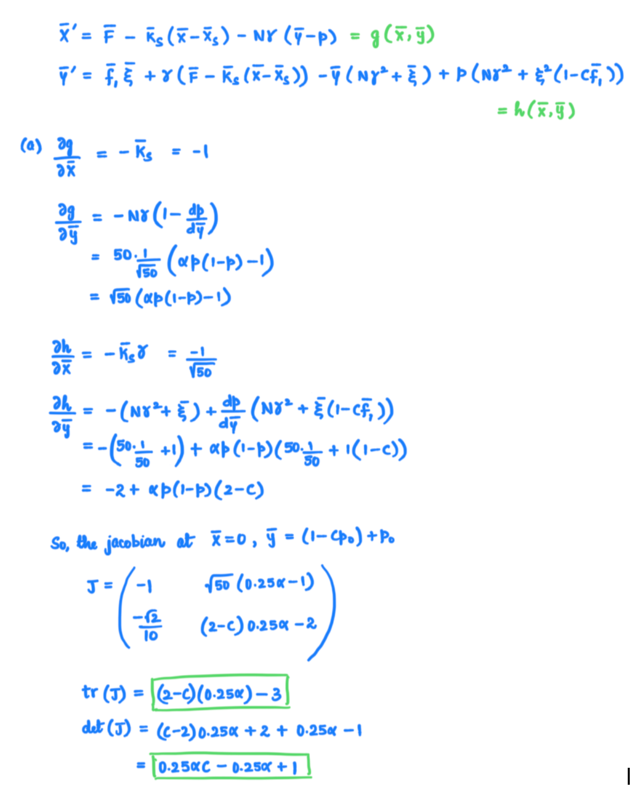

### Question (b).

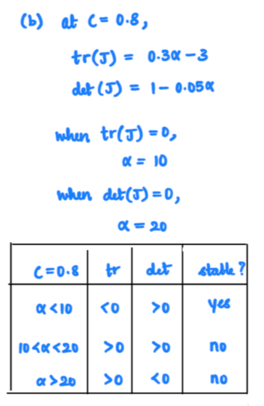

### Question (c).

%%Parameters
F = 0;
G = 1/(50^(1/2));
N = 50;
Ks = 1;
neta = 1;
f1 = 1;
p0 = .5;

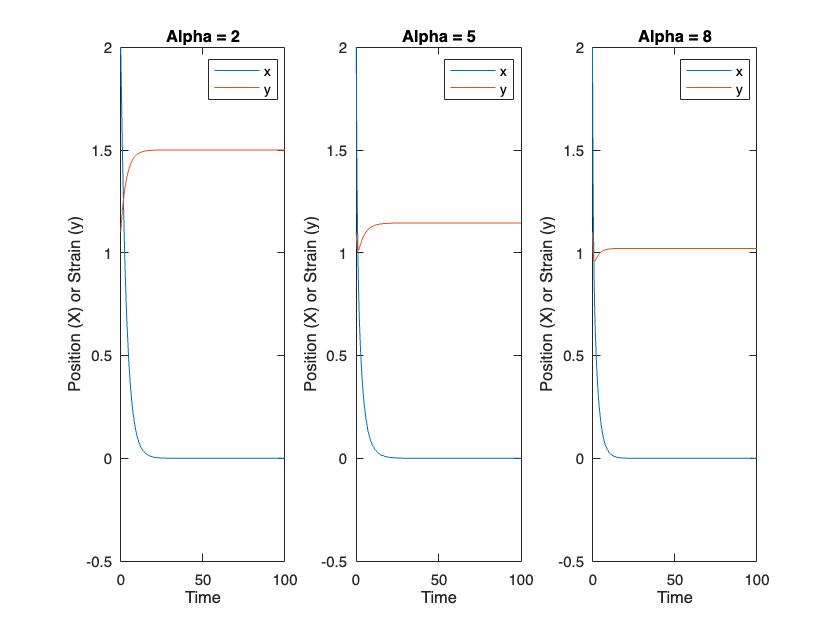

%% Solution - Case 1.
C = 0;
al_v = [2 5 8];
figure;
for i = 1:length(al_v)
    
    al = al_v(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1, length(al_v), i);
    plot(T, Y(1:end,1)); hold on;
    plot(T, Y(1:end, 2));

    % plot parameters.
    xlabel('Time');
    ylabel('Position (X) or Strain (y)');
    legend ('x', 'y');
    title(['Alpha = ', num2str(al)]);
end

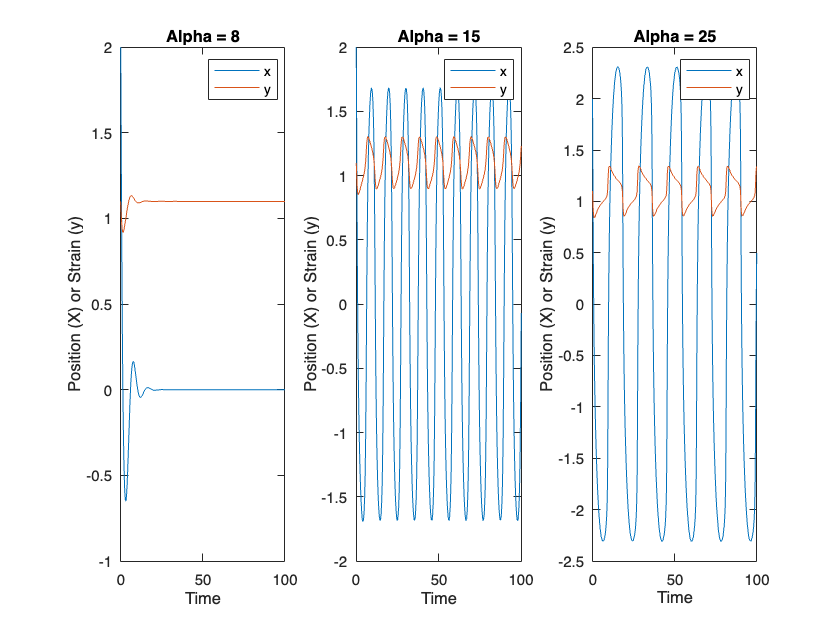

%% Solution - Case 2.
C = 0.8;
al_v = [8 15 25];
figure;
for i = 1:length(al_v)
    
    al = al_v(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1, length(al_v), i);
    plot(T, Y(1:end,1)); hold on;
    plot(T, Y(1:end, 2));

    % plot parameters.
    xlabel('Time');
    ylabel('Position (X) or Strain (y)');
    legend ('x', 'y');
    title(['Alpha = ', num2str(al)]);
end

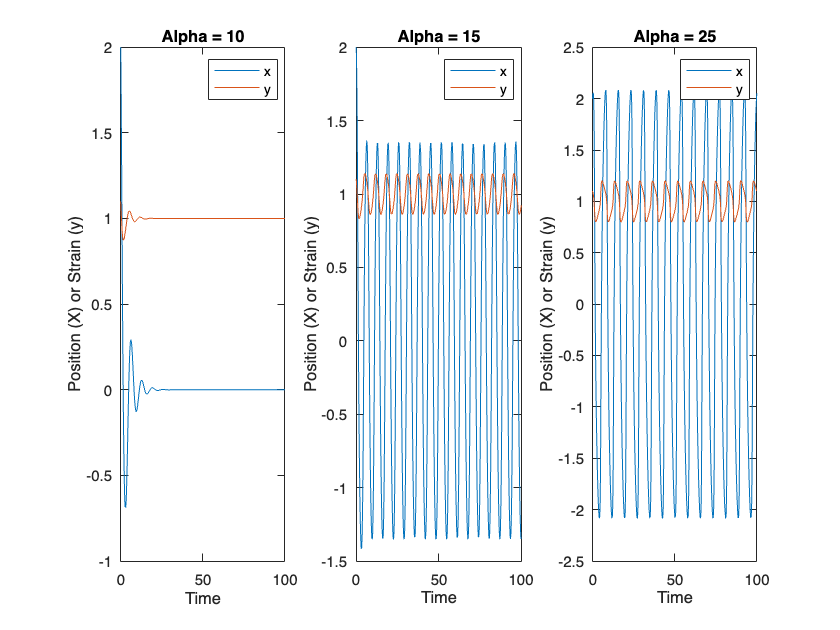

%% Solution - Case 3.
C = 1;
al_v = [10 15 25];
figure;
for i = 1:length(al_v)
    
    al = al_v(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1, length(al_v), i);
    plot(T, Y(1:end,1)); hold on;
    plot(T, Y(1:end, 2));

    % plot parameters.
    xlabel('Time');
    ylabel('Position (X) or Strain (y)');
    legend ('x', 'y');
    title(['Alpha = ', num2str(al)]);
end

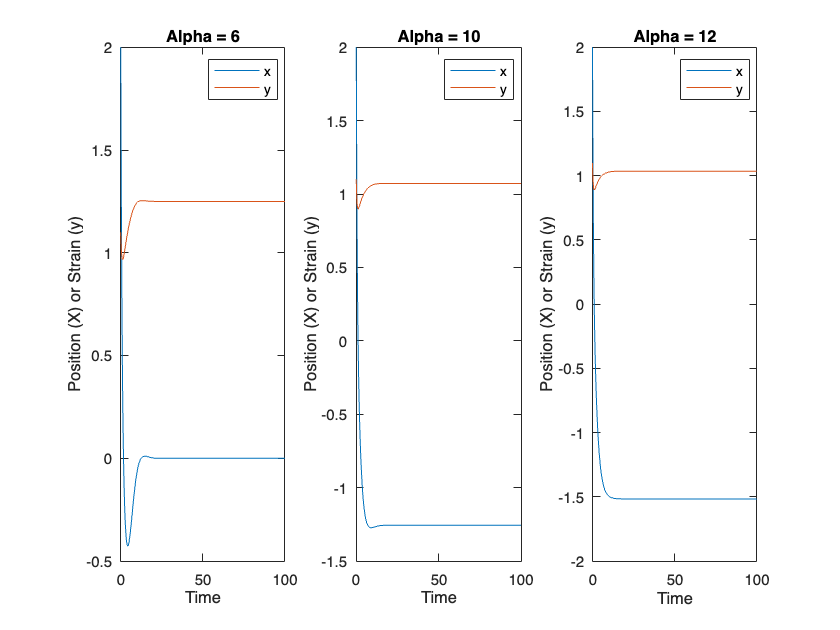

%% Solution - Case 4.
C = 0.5;
al_v = [6 10 12];
figure;
for i = 1:length(al_v)
    
    al = al_v(i);
    % other constants.
    y0 = f1*(1-C*p0) + p0;
    Xs = ((N * G)/Ks) * (y0-p0);
    A = (1-p0)/p0*exp(al*y0);
    % solve equation.
    dy = @(t,y)[F-Ks*(y(1)-Xs)-(N*G)*(y(2)-(1/(1+A*exp(-al*y(2)))));...
        (f1*neta) + G*(F-Ks*(y(1)-Xs)) - y(2)*(N*G^2 + neta) + ...
        (1/(1+A*exp(-al*y(2))))*(N*G^2 + neta*(1-C*f1))];
    [T, Y] = ode15s(dy,[0 100],[2 1.1]);
    
    % plot X and y against time.
    subplot(1, length(al_v), i);
    plot(T, Y(1:end,1)); hold on;
    plot(T, Y(1:end, 2));

    % plot parameters.
    xlabel('Time');
    ylabel('Position (X) or Strain (y)');
    legend ('x', 'y');
    title(['Alpha = ', num2str(al)]);
end

### Question (d)

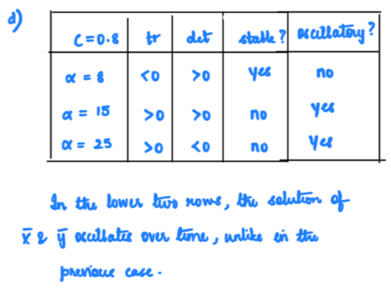

In the lower two rows, the solutions of X and y oscillate about the fixed point over time; unlike in the previous cases.

Adaptation motors of the hair cells play a crucial role in dampening responses to sustained stimuli -- over dampening prevents sustained oscillations. Hence, when the C value is too low, the adaptation motor is not weak enough and there is substantial damping effect. This can be seen in the plots for C = 0 and C = 0.5, where X and y quickly settle at the fixed point.

Alpha essentially determines the sensitivity of response of open probability to mechanical stimuli. When alpha is too low, there is a "dampening" effect in that a stronger, sustained stimulus would be required to effect the same amount of response. On the other hand, higher alpha would readily effect a response to stimuli and oscillations can happen more easily. This can be observed in the form of higher amplitude of oscillations associated with higher alpha values in any of the plots above that exhibit oscillations.

In effect, the adaptation motor must be weak enough to allow oscillations; transalting to a higher C value required for oscillations. And alpha must be large enough to enhance the mechanosensitivity to allow the hair bundles to oscillate easily. Both of these conditions must be satisfied to avoid damping the oscillations.

### Question (e)

Instability in a dynamical system is essentially a state from where small perturbations to the lead to large deviations from the expected behavior over time. Oscillations, on the other hand, are simply repititive motions around the unsteady equilibrium state. However, not all unstable systems exhibit oscillatory behavior. Some unstable systems may exhibit exponential growth or decay without oscillation, for instance, when the instability is not due to the presence of a restoring force, but rather due to other factors such as positive feedback or lack of damping.

Hence, the mere existence of instability does not guarantee oscillations; this further depends on the specific dynamics of the system, as is evident in the case if the Hudspeth model. Therein, although unstable fixed points exist at all values of C and alpha, they must also be large enough to prevent damping and allow oscillations. To generalize, the latter nuance that the parameter values must be in a specific range to allow the system to oscillate is the condition above instability that needs to be satisfied by the dynamics of the system.